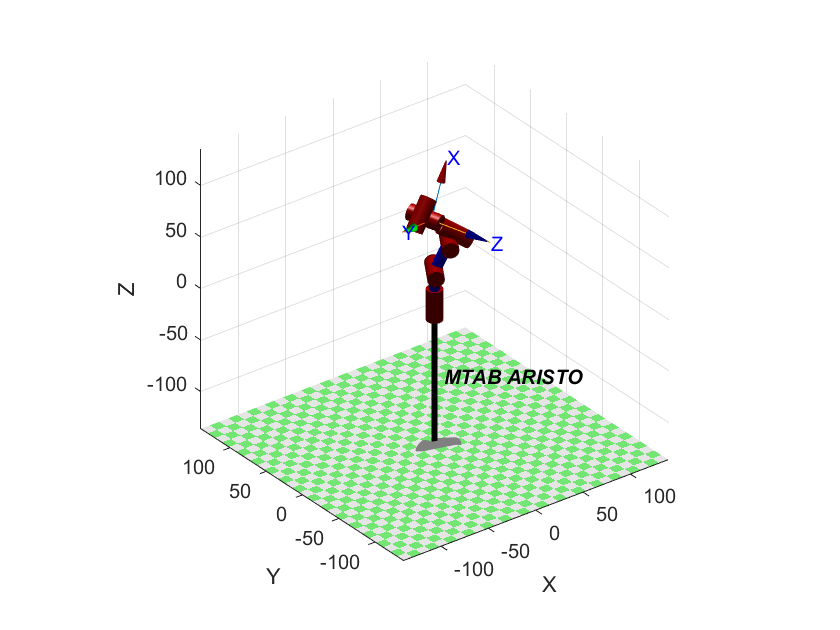

clc;
close all;
clear all;

% Defining the link of the robot manipulators
L1 = Link([0 32.2 0  pi/2]);
L2 = Link([0  0 30 0]);
L3 = Link([0 0 10 pi/2]);
L4 = Link([0 -37.5 10 pi/2]);
L5 = Link([0 0 10 pi/2]);
L6 = Link([0 6.3 0 0]);

% Defining the robot 
r = SerialLink([L1,L2,L3,L4,L5,L6]);r.name='MTAB ARISTO';

% Initial angles
qA = [0,0,0,0,0,0];

% Final angles
qB = [12,20,25,45,15,90];

% Time interval
t = 0:0.1:10;

% Trajector planning
[q,qd,qdd]=jtraj(qA,qB,t);

% PLotting the robot
plot(r,q)

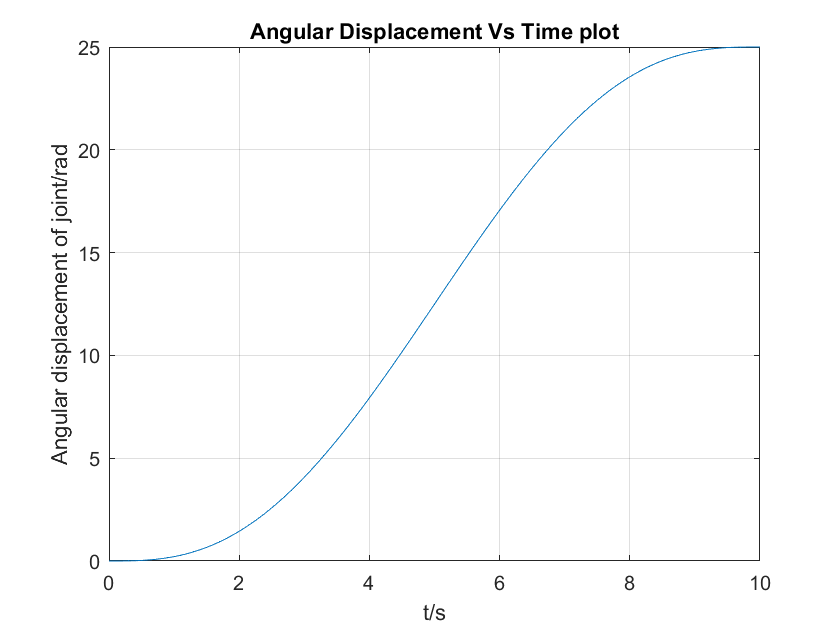


figure

% Position Vs Time plot
plot(t,q(:,3))
title('Angular Displacement Vs Time plot')
xlabel('t/s');
ylabel('Angular displacement of joint/rad');
grid on

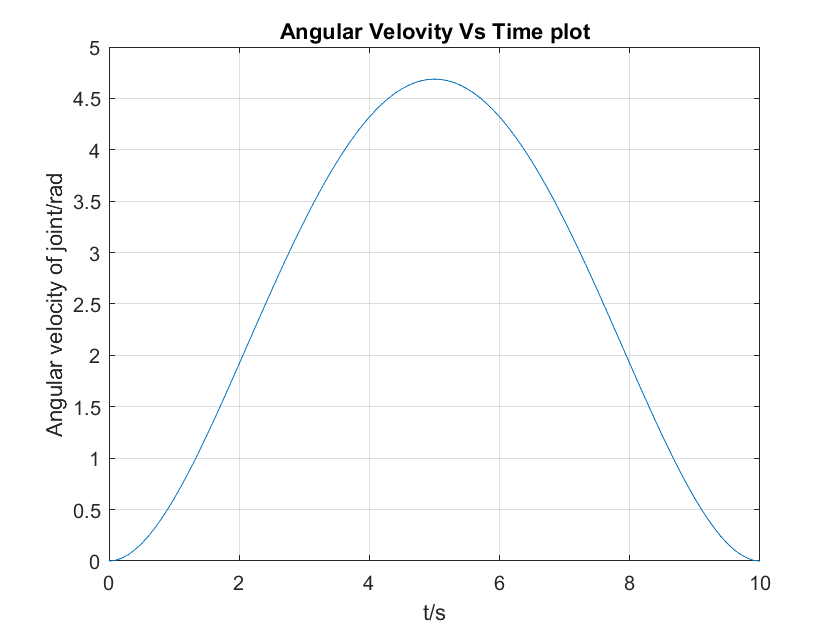


% Velovity Vs Time plot
plot(t,qd(:,3))
title('Angular Velovity Vs Time plot')
xlabel('t/s');
ylabel('Angular velocity of joint/rad');
grid on

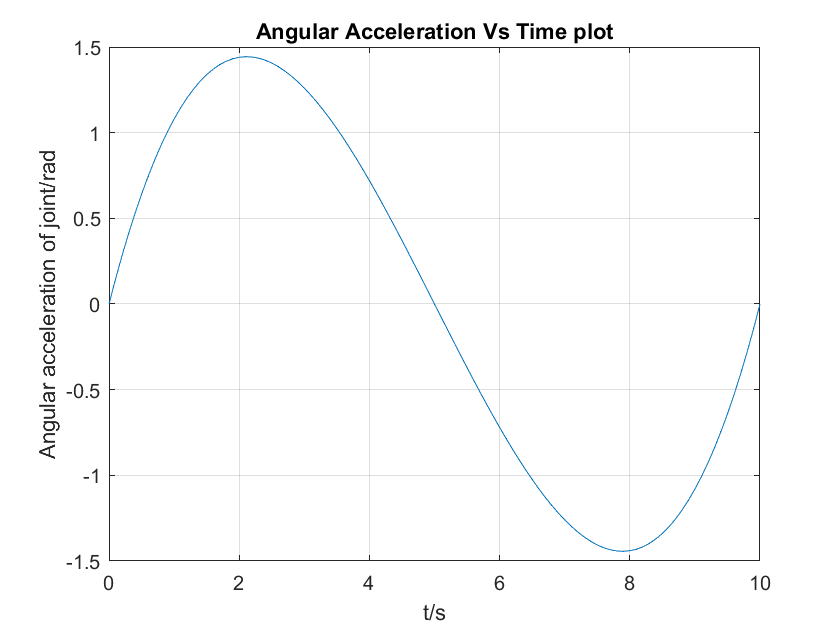


% Acceleration Vs Time plot
plot(t,qdd(:,3))
title('Angular Acceleration Vs Time plot')
xlabel('t/s');
ylabel('Angular acceleration of joint/rad');
grid on